Program for design of shaft, Problem Number 1.

Problem Statement :A shaft is required to transmit 1MW power at 220 rpm. The twist of shaft must not exceed more than 10 on a length of 15diameter. Determine the diameter of the shaft and shear stress induced. Take G = 80 kN/mm2 . 

Name: Avva Sai Pranav

USN : PES1201800861

Date : 13/09/2020

clc;
clear all;

Solution: 

Given Data:

P = 1𝑀𝑊 = 1 × 10^3 𝑘𝑊  

𝑛 = 220 𝑟𝑝𝑚 

Theta = 1 degree ( Initalized as theta)

L = 15𝑑

 𝐺 = 80𝑘𝑁/𝑚𝑚 = 80 × 10^3 𝑁/𝑚𝑚

P = 1000

P = 1000

n = 220-10

n = 210

L = 15;
G = 80*10^3

G = 80000

theta = 1

theta = 1

no = 100 

no = 100

fin_T =  zeros(no,1);
fin_n =  zeros(no,1);

[T] = Eqn_3_3_a(P,n)

T = 4.5476e+07

z = Eqn_3_2(T,G,L,theta)

Select the following:
1.The angular Deformation
2.The diameter 


z = 170.7652

d = z 

d = 170.7652

d = Table_3_5_a(d);

Standard size of the shaft (mm) using table 3.5(a) is : 


d = 180

disp('Shear Stress (N/mm^2) induced on the shaft is : ')

Shear Stress (N/mm^2) induced on the shaft is : 


Tu = Eqn_3_1(T,d);

To find the following trends:

1.Power vs rpm

2.Torque vs rpm

3.Diameter vs rpm

Intializing the 4 parameter arrays.

theta = 1;
n_array = 1:400;
P_array = n_array.*(T/(9.55*(10^6)));
T_array = n_array.^(-1).*(9.55*(10^6)*P);
d_array = ((T_array.*(584*L))./(G*theta)).^(1/3);

Trend of P vs N

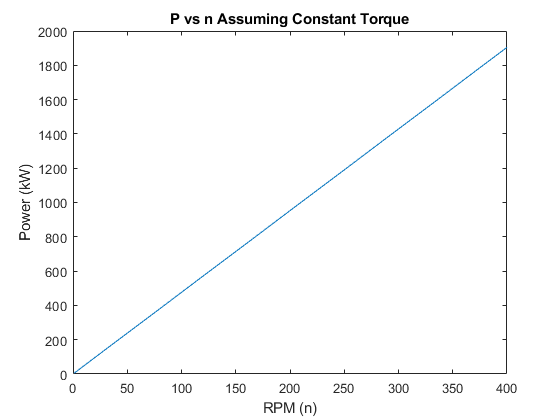

plot(n_array,P_array)
xlabel('RPM (n)')
ylabel('Power (kW)')
title('P vs n Assuming Constant Torque')

Plot Trend of T vs N

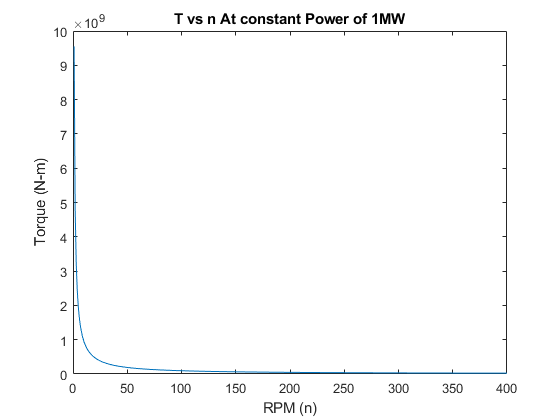

plot(n_array,T_array)
xlabel('RPM (n)')
ylabel('Torque (N-m)')
title('T vs n At constant Power of 1MW')

Plot Trend of d vs N

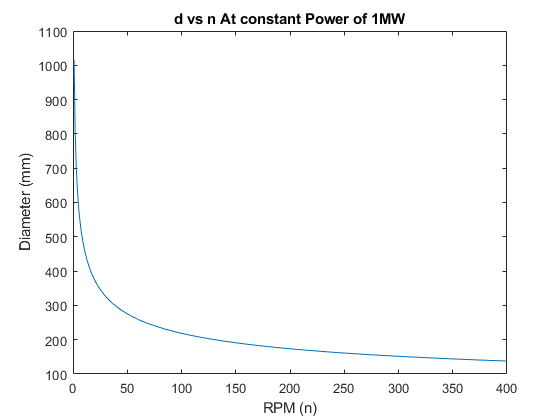

plot(n_array,d_array)
xlabel('RPM (n)')
ylabel('Diameter (mm)')
title('d vs n At constant Power of 1MW')